# Autocorrélation d'un signal sinusoidale

fs: Fréquence d'échantillonnage 

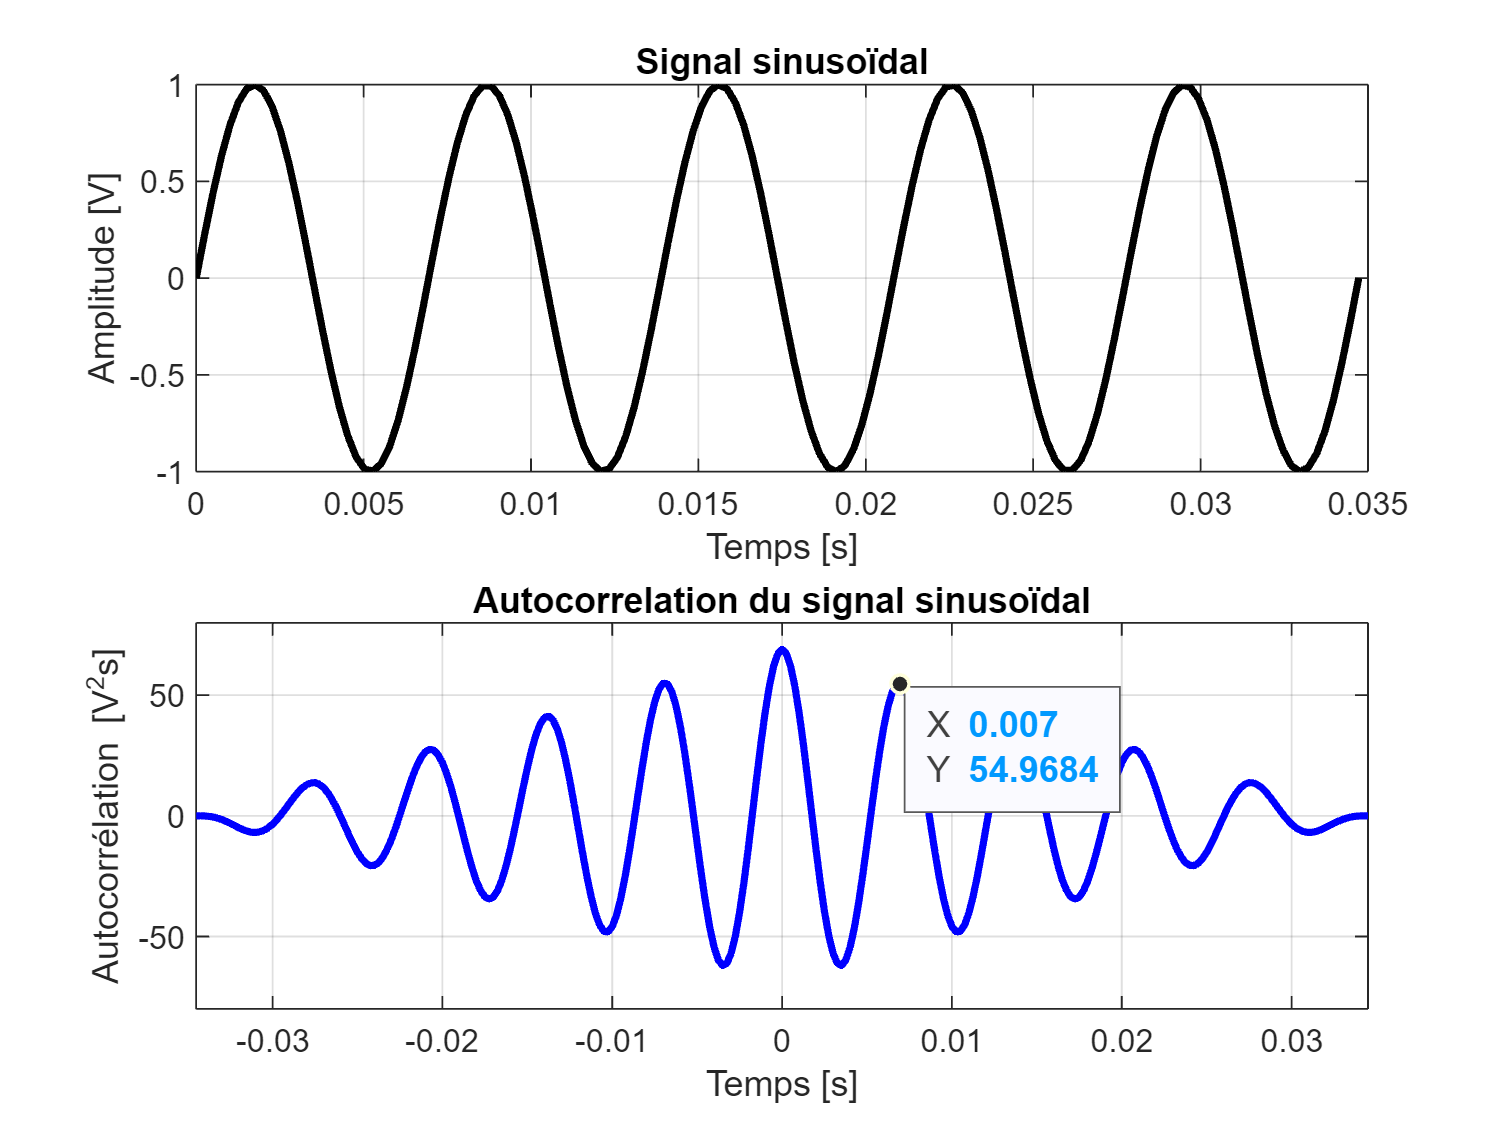

fs =20000;
f0 = 144;
T0 = 1 / f0;

t_max  = 5 * T0;
t      = linspace(0, t_max, ceil(fs/f0));

x_test = sin(2*pi*f0*t);

figure(1);
subplot(2,1,1);
plot(t, x_test, 'k-', 'LineWidth', 2);
grid;
title('Signal sinusoïdal');
xlabel('Temps [s]');
ylabel('Amplitude [V]');
%axis([min(t), max(t), -2, 2]);

[y, lags] = xcorr(x_test);
time      = t_max*f0*lags/fs;

subplot(2,1,2);
plot(time, y, 'b-', 'LineWidth', 2);
grid;
title('Autocorrelation du signal sinusoïdal');
xlabel('Temps [s]');
ylabel('Autocorrélation [V^2s]');
axis([min(time), max(time), -80, 80]);

subplot(2,1,2)
ax = gca;
chart = ax.Children(1);
datatip(chart,0.007,54.97);